# Current as Opposed to Resistance With User Interface

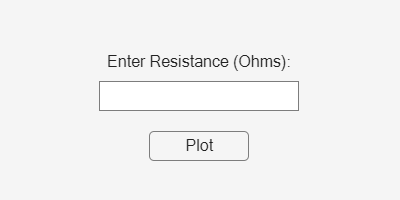

%{
ES115: Current as Opposed to Resistance With User Interface
Author: Jack O'charek
Date: 4-28-26
Purpose:
    Demonstrate the relationship between current and resistance, as both
    values can effect each other
Input: Resistance in ohms
Output:
    A plot will be created showing the relationship between current and
    resistence with the constant voltage value at 12 volts.
Engineering Algorithms:
    Clear screen and delete all variables
    Define constants - voltage
    Create user interface screen
    Create text label
    Link user interface screen with button to generate plot
    Use callback function with Ohm's law to create the function for plot
    Finalize generated plot including range for resistance
%}
clc;
clear;
close all;

V_supply = 12;  

fig = figure('Position', [500, 300, 400, 200], ...
             'Name', 'Resistance Input', ...
             'NumberTitle', 'off');

uicontrol('Style', 'text', ...
          'Position', [50, 120, 300, 30], ...
          'String', 'Enter Resistance (Ohms):', ...
          'FontSize', 12);

res_input = uicontrol('Style', 'edit', ...
                      'Position', [100, 90, 200, 30], ...
                      'FontSize', 12);

uicontrol('Style', 'pushbutton', ...
          'Position', [150, 40, 100, 30], ...
          'String', 'Plot', ...
          'FontSize', 12, ...
          'Callback', @(src,event) plotGraph(res_input, V_supply));


function plotGraph(res_input, V_supply)

    R_user = str2double(get(res_input, 'String'));
    
    if isnan(R_user) || R_user <= 0
        errordlg('Please enter a valid positive resistance value.');
        return;
    end

    R = linspace(1, 1000, 200); 
    
    I = V_supply ./ R;
    
    I_user = V_supply / R_user;

    figure('Position', [400, 150, 700, 500]);

    plot(R, I, 'm', 'LineWidth', 2); hold on;
    plot(R_user, I_user, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
    
    xlabel('Resistance (Ohms)');
    ylabel('Current (A)');
    title('Current vs Resistance');
    legend('Current Curve','Selected Point');
    grid on;

end